# Parameter Setting

len = 200;
n = 2;
m = 4;
sig = 1.2;
bias = 0;
useBias = true;

## Display Sample Array

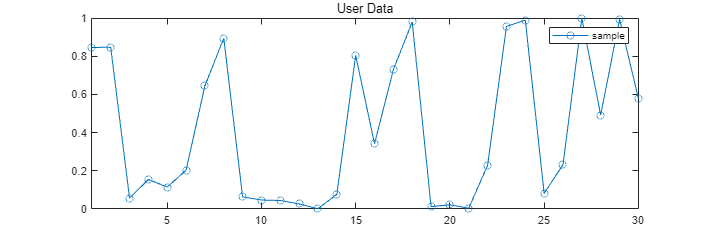

y = genSampleArray(len, sig, n, m, useBias, bias);

fig = figure();
fig.Position(3:4) = [1200 400];
plot(y, "o-")
legend("sample")
xlim([1; 30])
title("User Data")

## Pred Value

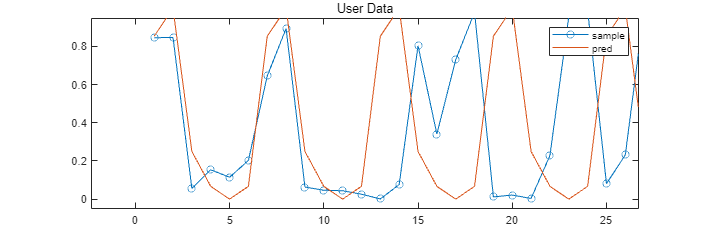

hold on
py = genPredDataArray(len, n, m, 0);
plot(py)
legend(["sample" "pred"])
hold off

## Calculate VAR

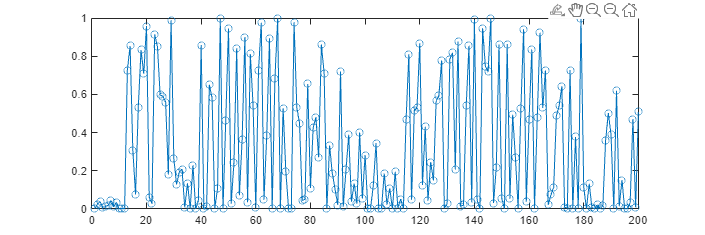

difsquare = zeros(1, len);

for i=1:len
    difsquare(i) = ((py(i) - y(i))).^2;
end

plot(difsquare, "o-")

sum(difsquare)/len

ans = 0.3250

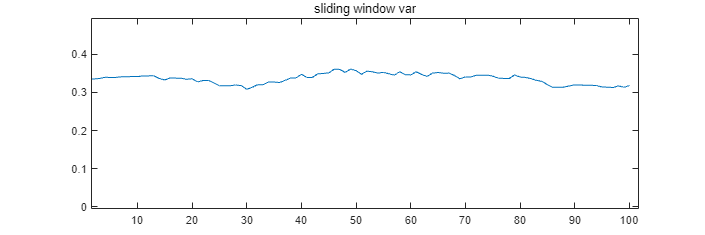

%% Sliding Window Method
windowSize = 100;
sizedVAR = zeros(1, len-windowSize);
for i=1:len-windowSize
    sizedVAR(i) = sum(difsquare(i:i+windowSize))/windowSize;
end

plot(sizedVAR)
ylim([0 0.5])
title("sliding window var")

## Random User Data Generator

function y=genSampleArray(length, sig, n, m, useBias, defaultBias)
    % random breath data Used User data
    y = zeros(1, length);
    
    bias = defaultBias;
    for i = 1:length
        breath_type = mod(i-1 + bias, n + m);
        if breath_type+1 > n % exhale
            y(i) = sin(normrnd(pi * 3 / 2, sig))/2 + 0.5;
            if y(i) > 0.7 && useBias
                bias = bias + 1;
            end
        else
            y(i) = sin(normrnd(pi / 2, sig))/2 + 0.5;
            if y(i) <= 0.3 && useBias
                bias = bias + 1;
            end
        end
    end
end

%% Generate Predict Data Array
function py = genPredDataArray(length, n, m, defaultBias)
    py = zeros(1, length);
    for i = 1:length
        breath_type = mod(i-1 + defaultBias, n + m);
        if breath_type+1 > n % exhale
            py(i) = sin(pi * (breath_type + 1 - n) / (m+2) + pi)/2 + 0.5;
        else
            py(i) = sin(pi * (breath_type + 1) / (n+2))/2 + 0.5;
        end
    end

end